# Дубинка подброшенная в воздух

#### Пример решения системы обычных дифференциальных уравнений (ДУ) в MATLAB адаптивным решателем.

#### Описание объекта моделирования

Дубинка представляет собой невесомый стержень длинной $L$ на концах которого закрепленны две массы $m_1$и $m_2$.

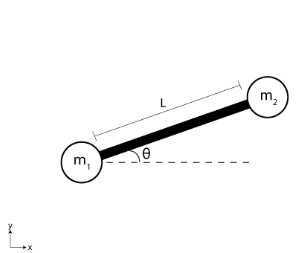

Дубинка подбрасывается в воздух и двигается в вертикальной плоскости $\textrm{XY}$ в поле тяжести.

Угол $\theta$ показан на рисунке, координаты центра масс примем за $\left(x,y\right)$.

Пусть параметры системы будут следующими:


$$\begin{array}{l}
x_0 =1\;-\;\textrm{начальное}\textrm{положение}\textrm{по}\;x\;\left(m\right)\\
y_0 =1\;-\;\textrm{начальное}\textrm{положение}\textrm{по}\;y\;\left(m\right)\\
\theta_0 =0\;-\;\textrm{начальное}\textrm{положение}\textrm{по}\textrm{углу}\;\left(\textrm{rad}\right)\\
V_{\textrm{x0}} =5\;-\;\textrm{начальная}\;\textrm{скорость}\;\textrm{по}\;x\;\left(m/s\right)\\
V_{\textrm{y0}} =15\;-\;\textrm{начальная}\;\textrm{скорость}\;\textrm{по}\;y\;\left(m/s\right)\\
\omega_0 =4\;-\;\textrm{начальная}\;\textrm{угловая}\;\textrm{скорость}\;\left(\textrm{rad}/s\right)\\
t_{\textrm{end}} =3-\textrm{конец}\;\textrm{промежутка}\;\textrm{времени}\;\left(s\right)
\end{array}$$


#### Найдем систему ДУ относительно центра масс в терминах Лагранжевой механики


$$\begin{array}{l}
\frac{\mathrm{d}}{\mathrm{d}t}\frac{\mathrm{d}}{\mathrm{d}q^{\prime } }L\left(t,q,q^{\prime } \right)-\frac{\mathrm{d}}{\mathrm{d}q}L\left(t,q,q^{\prime } \right)=0\;\;\;\left(1\right)\\
\mathrm{где}\;q=\;\left(x,y\right)\ldotp 
\end{array}$$


Запишем энергию вращения системы $\mathrm{E_{rot}}=\frac{J\,\omega ^2}{2}$, энергию движения $\mathrm{E_{mov}}=\frac{M\,V^2}{2}$, потенциальную энергию $U=M\,g\,h$;

где: $q' = V=\sqrt{{\left(\frac{\partial }{\partial t} x\left(t\right)\right)}^2+{\left(\frac{\partial }{\partial t} y\left(t\right)\right)}^2}$ - скорость дубинки, $J$ - момент инерции, $M$ - масса дубинки, $\omega$ - угловая скорость, $g$ - ускорение свободного падения, $h$ - высота.

syms Erot Emov J omega V M U g h T x(t) y(t) theta(t) l % зададим символьные переменные
eqnErot = Erot == 1/2*J*omega^2; % энергия вращения
eqnEmov = Emov == 1/2*M*V^2; % энергия движения
eqnU = U == M*g*h; % потенциальная энергия
eqnV = V == sqrt((diff(x,t))^2+(diff(y,t))^2); % скорость

Из закона сохранения энергии найдем выражение $L\left(t,q,q^{\prime } \right)$.

eqnT = T == rhs(eqnErot) + rhs(eqnEmov); 
eqnT = subs(eqnT,[omega V],[diff(theta,t) rhs(eqnV)]); % кинетическая энергия
eqnU = subs(eqnU,h,y); % потенциальная энергия
syms L
eqnL = L == T - U;
eqnL = subs(eqnL,[T U],[rhs(eqnT) rhs(eqnU)]) % найдем функцию Лагранжа

$$eqnL = L=\frac{M\,\left({\left(\frac{\partial }{\partial t}x\left(t\right)\right)}^{2}+{\left(\frac{\partial }{\partial t}y\left(t\right)\right)}^{2}\right)}{2}+\frac{J\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}}{2}-M\,g\,y\left(t\right)$$

Найдем уравнения движения дубинки подставив функцию Лагранжа в выражение $\left(1\right)$:

eqns = functionalDerivative(-rhs(eqnL),[x y theta]) == [0;0;0] % минимизируем функционал

$$eqns(t) = \left(\begin{array}{c} M\,\frac{\partial^{2}}{\partial t^{2}}x\left(t\right)=0\\ M\,\frac{\partial^{2}}{\partial t^{2}}y\left(t\right)+M\,g=0\\ J\,\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)=0 \end{array}\right)$$

vars = [x(t); y(t); theta(t)]; % переменные

#### Решим систему уравнений

Для этого уменьшаем порядок системы до первого, переписываем систему в виде $M\left(t,x\left(t\right)\right)\cdot x\left(t\right)=F\left(t,x\left(t\right)\right)$, составляем пользовательскую функцию и решаем ее с помощью ode45.

[newEqs,newVars] = reduceDifferentialOrder(eqns,vars); % найдем эквивалентную систему первого порядка
[Mass,f] = massMatrixForm(newEqs,newVars); % найдем массовую матрицу для системы вида M(t,x(t))*x(t)'==F(t,x(t)) 
mass = odeFunction(Mass, newVars,J,M); % конвертируем массовую матрицу в пользовательскую функцию
func = odeFunction(f,newVars,l,g,M); % запишем пользовательскую функцию для F(t,x(t))
% зададим параметры
init_cond % инициализация начальных условий и параметров
y0est = [x0; y0; theta0; vx0; vy0; omega]; % вектор начальных состояний
tend = 3; % конец промежутка времени
opts = odeset('Mass',@(t,q) mass(t,q,Ixx,Msum)); % настройки решателя
Sol = ode45(@(t,q) func(t,q,l,g,Msum),[0 tend],y0est,opts); % решаем систему численно

#### Результаты

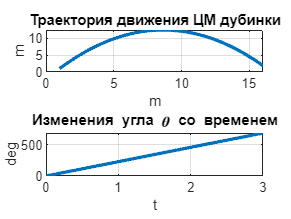

step = 0.01; % шаг по времени
t = 0:step:tend; % промежуток времени
X = deval(Sol,t,1); % решение для x(t)
Y = deval(Sol,t,2); % решение для y(t)
Th = deval(Sol,t,3);% решение для theta(t)
figure
subplot(2,1,1)
plot(X,Y,'LineWidth',2)
grid on
title('Траектория движения ЦМ дубинки')
xlabel('m')
ylabel('m')
subplot(2,1,2)
plot(t,rad2deg(Th),'LineWidth',2)
grid on
title('Изменения угла \theta со временем')
xlabel('t')
ylabel('deg')

#### Построим анимацию

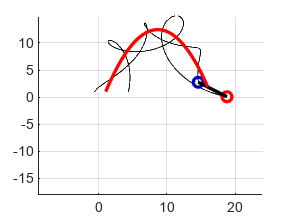

L_CM = (m1*0+m2*l)/Msum; % найдем центр масс
animateBaton(t,X,Y,Th,L_CM,l) % строим анимацию

Сохраним результаты

Xart1 = X; Yart1 = Y; Thart1 = Th;
save('ArticlePart1Result','Xart1','Yart1','Thart1')

function animateBaton(t,X,Y,Th,X_CM,l)

figure
A1 = axes;
        A1.XLim = [-10 30];
        A1.YLim = [-20 20];
grid on
Mass1 = line([0 0],[0 0],'Color','b','LineWidth',2,'Marker','o');
Mass2 = line([0 0],[0 0],'Color','r','LineWidth',2,'Marker','o');
Line_1 = line([0 0],[0 0],'Color','k','LineWidth',2);

a1 = animatedline;
a2 = animatedline;
a3 = animatedline('Color','r','LineWidth',2);
for i = 1:length(t)
    Mass1.XData = X(i)-X_CM*cos(Th(i));
    Mass1.YData = Y(i)-X_CM*sin(Th(i));
    Mass2.XData = X(i)+(l-X_CM)*cos(Th(i));
    Mass2.YData = Y(i)+(l-X_CM)*sin(Th(i));
    Line_1.XData = [X(i)-X_CM*cos(Th(i)) X(i)+(l-X_CM)*cos(Th(i))];
    Line_1.YData = [Y(i)-X_CM*sin(Th(i)) Y(i)+(l-X_CM)*sin(Th(i))];
    addpoints(a1,X(i)-X_CM*cos(Th(i)),Y(i)-X_CM*sin(Th(i)));
    addpoints(a2,X(i)+(l-X_CM)*cos(Th(i)),Y(i)+(l-X_CM)*sin(Th(i)));
    addpoints(a3,X(i),Y(i));
    drawnow limitrate
    pause(0.1)
end
end